# sub-16

This code begins by importing raw SEEG data and converting to Fieldtrip format. 

It then edit the SEEG channel labels, inspects the SEEG data, and remove any bad channels.

Following this, the code redefines resting, 0-back, 1-back and 2-back blocks using TRIG or Event channel signals.   

## Set working directory

clc;clear;close all;
addpath Z:\xwiEEG_WorkingMemory_zhangshen\github_replication\function\fieldtrip-20231220;
ft_defaults;
addpath Z:\xwiEEG_WorkingMemory_zhangshen\github_replication\function\iEEGPrep
iEEGPrep_initial;
addpath Z:\xwiEEG_WorkingMemory_zhangshen\github_replication\function\neuracle-eegfile-reader-master
addpath Z:\xwiEEG_WorkingMemory_zhangshen\github_replication\function
cd  Z:\xwiEEG_WorkingMemory_zhangshen\github_replication\data_prep\BIDS;
subID = 'sub-16';
cd(fullfile(subID, 'ieeg'));

## Import SEEG data and edit channel labels

evtfile = [subID, '_task-nback_run-1_evt.bdf'];
iEEGfile = [subID, '_task-nback_run-1_ieeg.bdf'];
[Data, Event] = f_readbdf(iEEGfile, evtfile);

BDF+ file format detected, the BDF Annotation channel will be skipped when reading data
processing channel { 'A1' 'A2' 'A3' 'A4' 'A5' 'A6' 'A7' 'A8' 'A9' 'A10' 'A11' 'A12' 'B1' 'B2' 'B3' 'B4' 'B5' 'B6' 'B7' 'B8' 'B9' 'B10' 'B11' 'B12' 'B13' 'B14' 'B15' 'B16' 'C1' 'C2' 'C3' 'C4' 'C5' 'C6' 'C7' 'C8' 'C9' 'C10' 'D1' 'D2' 'D3' 'D4' 'D5' 'D6' 'D7' 'D8' 'D9' 'D10' 'D11' 'D12' 'E1' 'E2' 'E3' 'E4' 'E5' 'E6' 'E7' 'E8' 'E9' 'E10' 'E11' 'E12' 'E13' 'E14' 'E15' 'E16' 'F1' 'F2' 'F3' 'F4' 'F5' 'F6' 'F7' 'F8' 'F9' 'F10' 'F11' 'F12' 'F13' 'F14' 'F15' 'F16' 'G1' 'G2' 'G3' 'G4' 'G5' 'G6' 'G7' 'G8' 'G9' 'G10' 'G11' 'G12' 'G13' 'G14' 'G15' 'G16' 'ECG' }
reading and preprocessing
reading and preprocessing trial 1 from 1

the call to "ft_preprocessing" took 32 seconds


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% remove bad channels
badChan = {'-A12', '-B1', '-B2', '-B3', '-B14', '-B15', '-B16', ...
    '-E1', '-E2', ...
    '-F1', '-F2', '-F3', '-F4', '-D1', '-D2', '-ECG'};
cfg = [];
cfg.channel = [{'all'}, badChan];
Data = ft_preprocessing(cfg, Data);

the call to "ft_selectdata" took 1 seconds
preprocessing
preprocessing trial 1 from 1

the call to "ft_preprocessing" took 1 seconds


## Inspects SEEG data

BPfreq = [1, 120];
DataPrep = f_filter_bandpass(Data, BPfreq);

the call to "ft_selectdata" took 0 seconds
preprocessing
preprocessing trial 1 from 1

the call to "ft_preprocessing" took 16 seconds


RSfreq = 250;
DataPrep = f_filter_resample(DataPrep, RSfreq);

the input is raw data with 83 channels and 1 trials
the call to "ft_selectdata" took 0 seconds
resampling data
resampling data in trial 1 from 1

original sampling rate = 2000 Hz
new sampling rate = 250 Hz
the call to "ft_resampledata" took 6 seconds


chanGroups = f_chanGroup(DataPrep.label);
refMethod = 'Laplace';
DataPrep = f_reref_SEEG(DataPrep, refMethod, chanGroups);

 In fixsampleinfo at line 100
 In ft_datatype_raw at line 148
 In ft_checkdata at line 279
 In ft_preprocessing at line 275



 In fixsampleinfo at line 105
 In ft_datatype_raw at line 148
 In ft_checkdata at line 279
 In ft_preprocessing at line 275

the call to "ft_selectdata" took 0 seconds
preprocessing
the call to "ft_preprocessing" took 0 seconds


 In fixsampleinfo at line 100
 In ft_datatype_raw at line 148
 In ft_checkdata at line 279
 In ft_preprocessing at line 275



 In fixsampleinfo at line 105
 In ft_datatype_raw at line 148
 In ft_checkdata at line 279
 In ft_preprocessing at line 275

the call to "ft_selectdata" took 0 seconds
preprocessing
the call to "ft_preprocessing" took 0 seconds


 In fixsampleinfo at line 100
 In ft_datatype_raw at line 148
 In ft_checkdata at line 279
 In ft_preprocessing at line 275



 In fixsampleinfo at line 105
 In ft_datatype_raw at line 148
 In ft_checkdata at line 279
 In ft_preprocessing at line 275

the call to "ft_selectdata" took 0 seconds
preprocessing
the call to "ft_preprocessing" took 0 seconds


 In fixsampleinfo at line 100
 In ft_datatype_raw at line 148
 In ft_checkdata at line 279
 In ft_preprocessing at line 275



 In fixsampleinfo at line 105
 In ft_datatype_raw at line 148
 In ft_checkdata at line 279
 In ft_preprocessing at line 275

the call to "ft_selectdata" took 0 seconds
preprocessing
the call to "ft_preprocessing" took 0 seconds


 In fixsampleinfo at line 100
 In ft_datatype_raw at line 148
 In ft_checkdata at line 279
 In ft_preprocessing at line 275



 In fixsampleinfo at line 105
 In ft_datatype_raw at line 148
 In ft_checkdata at line 279
 In ft_preprocessing at line 275

the call to "ft_selectdata" took 0 seconds
preprocessing
the call to "ft_preprocessing" took 0 seconds


 In fixsampleinfo at line 100
 In ft_datatype_raw at line 148
 In ft_checkdata at line 279
 In ft_preprocessing at line 275



 In fixsampleinfo at line 105
 In ft_datatype_raw at line 148
 In ft_checkdata at line 279
 In ft_preprocessing at line 275

the call to "ft_selectdata" took 0 seconds
preprocessing
the call to "ft_preprocessing" took 0 seconds


 In fixsampleinfo at line 100
 In ft_datatype_raw at line 148
 In ft_checkdata at line 279
 In ft_preprocessing at line 275



 In fixsampleinfo at line 105
 In ft_datatype_raw at line 148
 In ft_checkdata at line 279
 In ft_preprocessing at line 275

the call to "ft_selectdata" took 0 seconds
preprocessing
the call to "ft_preprocessing" took 0 seconds
concatenating over the "chan" dimension
the call to "ft_selectdata" took 0 seconds
the call to "ft_appenddata" took 1 seconds


the input is raw data with 83 channels and 1 trials


 In ft_databrowser at line 346

detected   0 visual artifacts
the different artifact types correspond to the following colors:
  visual = pink
the different event types correspond to the following colors:


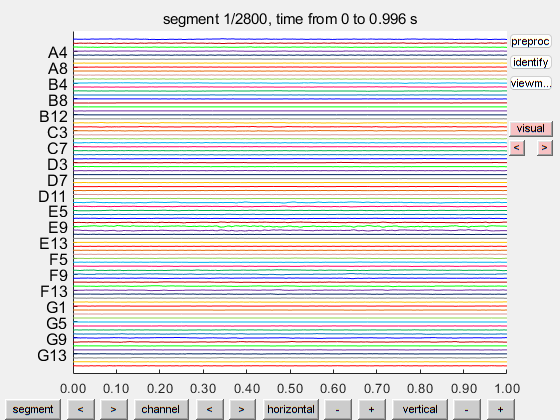

------------------------------------------------------------------------------------
You can use the following keyboard buttons in the databrowser
1-9                : select artifact type 1-9
shift 1-9          : select previous artifact of type 1-9 (does not work with numpad)
alt 1-9            : select next artifact of type 1-9
arrow-left         : previous trial
arrow-right        : next trial
shift arrow-up     : increase vertical scaling
shift arrow-down   : decrease vertical scaling
shift arrow-left   : increase horizontal scaling
shift arrow-down   : decrease horizontal scaling
t                  : open trial or segment selection dialog
c                  : open channel selection dialog
h                  : open horizontal scaling dialog
v                  : open vertical scaling dialog
p                  : open preproc editor
i                  : identify a specific channel
m                  : toggles between cfg.viewmode options
s                  : toggles between cfg.selec

cfg = [];
cfg.viewmode = 'vertical';
ft_databrowser([], DataPrep);

fsample = Data.fsample;

## Redefine resting block

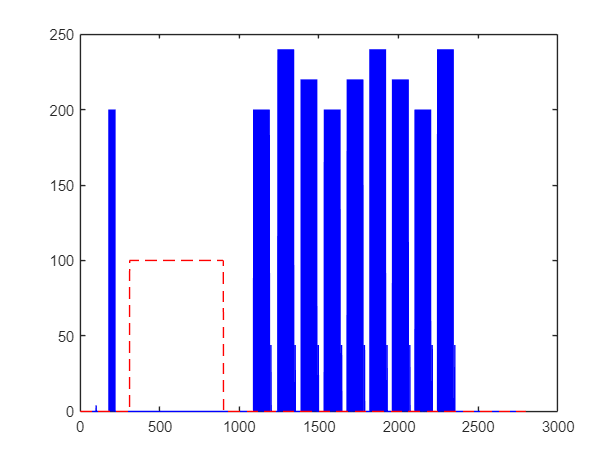

rsValue = 100;
rsStart = 600000;
rsStart = rsStart + ceil(10*fsample);
rsEnd = rsStart + ceil(10*60*fsample-10*fsample);
rsPointer = zeros(size(Event));
rsPointer(rsStart:rsEnd) = 1;
figure;
plot(Data.time{1}, Event, '-b');
hold on;
plot(Data.time{1}, rsValue*rsPointer, '--r');
hold off;

% construct resting data
rsSignals = Data.trial{1}(:, rsStart:rsEnd);
sampleinfo = [1, size(rsSignals, 2)];
rsTime = Data.time{1}(rsStart:rsEnd);
rsData.cfg = Data.cfg;
rsData.fsample = fsample;
rsData.label = Data.label;
rsData.hdr = Data.hdr;
rsData.trial{1} = rsSignals;
rsData.time{1} = rsTime;
rsData.sampleinfo = sampleinfo;
save([subID, '_task-resting_run-1_ieeg.mat'], 'rsData');
disp('******************************************************');

******************************************************


## Redefine 0-back blocks

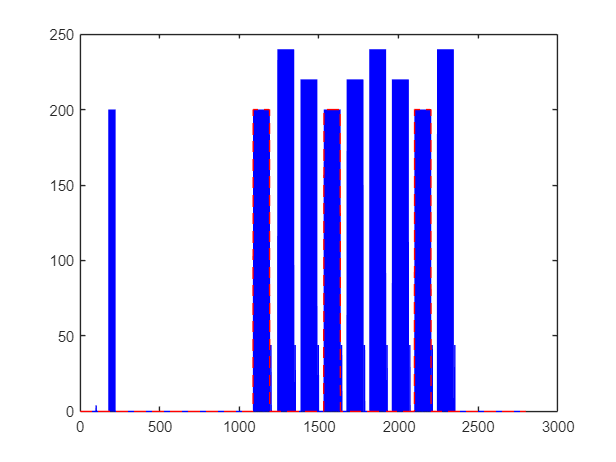

nb0Value = 200;
nb0Pointer = Event == nb0Value;
nb0Start = find(diff(nb0Pointer)==1);
nb0Start(nb0Start<600000) = [];
nb0End = find(diff(nb0Pointer)==-1);
nb0End(nb0End<600000) = [];
nb0Pointer = zeros(size(Event));
for nn = 1:length(nb0Start)
    nb0Pointer(nb0Start(nn)-ceil(3*fsample):nb0End(nn)+ceil(3*fsample))=1;
end
figure;
plot(Data.time{1}, Event, '-b');
hold on;
plot(Data.time{1}, nb0Value*nb0Pointer, '--r');
hold off;

% Construct data
nb0Start = find(diff(nb0Pointer)==1);
nb0End = find(diff(nb0Pointer)==-1);
nb0Data.cfg = Data.cfg;
nb0Data.fsample = fsample;
nb0Data.label = Data.label;
nb0Data.hdr = Data.hdr;
for nRun = 1:3
    sampleinfo = [nb0Start(nRun), nb0End(nRun)];
    TRIG{nRun} = Event(sampleinfo(1):sampleinfo(2));
    nb0Signal = Data.trial{1}(:, sampleinfo(1):sampleinfo(2));
    nb0Time = Data.time{1}(sampleinfo(1):sampleinfo(2));
    nb0Data.sampleinfo(nRun, :) = sampleinfo;
    nb0Data.time{nRun} = nb0Time;
    nb0Data.trial{nRun} = nb0Signal;
end
save([subID, '_task-0back_run-1_ieeg.mat'], 'nb0Data', 'TRIG');
disp('******************************************');

******************************************


## Redefine 1-back blocks

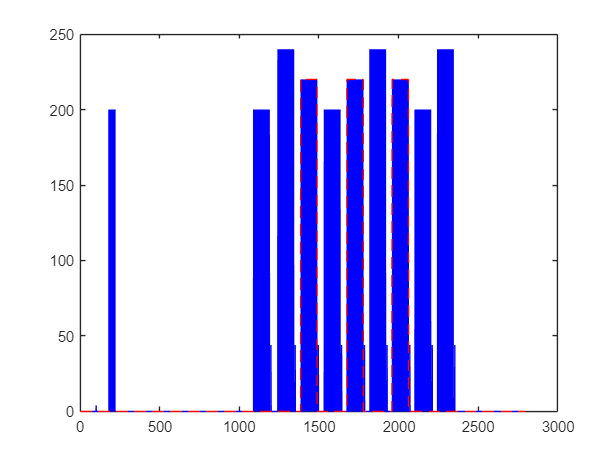

nb1Value = 220;
nb1Pointer = Event == nb1Value;
nb1Start = find(diff(nb1Pointer)==1);
nb1End = find(diff(nb1Pointer)==-1);
nb1Pointer = zeros(size(Event));
for nn = 1:length(nb1Start)
    nb1Pointer(nb1Start(nn)-ceil(3*fsample):nb1End(nn)+ceil(3*fsample))=1;
end
figure;
plot(Data.time{1}, Event, '-b');
hold on;
plot(Data.time{1}, nb1Value*nb1Pointer, '--r');
hold off;

% Construct data
nb1Start = find(diff(nb1Pointer)==1);
nb1End = find(diff(nb1Pointer)==-1);
nb1Data.cfg = Data.cfg;
nb1Data.fsample = fsample;
nb1Data.label = Data.label;
nb1Data.hdr = Data.hdr;
for nRun = 1:3
    sampleinfo = [nb1Start(nRun), nb1End(nRun)];
    TRIG{nRun} = Event(sampleinfo(1):sampleinfo(2));
    nb1Signal = Data.trial{1}(:, sampleinfo(1):sampleinfo(2));
    nb1Time = Data.time{1}(sampleinfo(1):sampleinfo(2));
    nb1Data.sampleinfo(nRun, :) = sampleinfo;
    nb1Data.time{nRun} = nb1Time;
    nb1Data.trial{nRun} = nb1Signal;
end
save([subID, '_task-1back_run-1_ieeg.mat'], 'nb1Data', 'TRIG');
disp('*************************************');

*************************************


## Redefine 2-back blocks

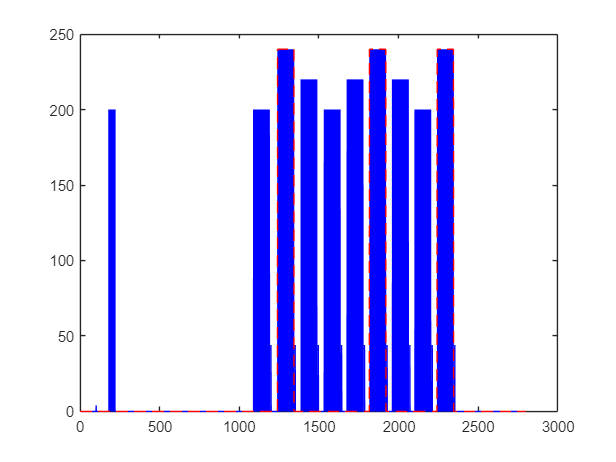

nb2Value = 240;
nb2Pointer = Event == nb2Value;
nb2Start = find(diff(nb2Pointer)==1);
nb2End = find(diff(nb2Pointer)==-1);
nb2Pointer = zeros(size(Event));
for nn = 1:length(nb2Start)
    nb2Pointer(nb2Start(nn)-ceil(3*fsample):nb2End(nn)+ceil(3*fsample))=1;
end
figure;
plot(Data.time{1}, Event, '-b');
hold on;
plot(Data.time{1}, nb2Value*nb2Pointer, '--r');
hold off;

% Construct data
nb2Start = find(diff(nb2Pointer)==1);
nb2End = find(diff(nb2Pointer)==-1);
nb2Data.cfg = Data.cfg;
nb2Data.fsample = fsample;
nb2Data.label = Data.label;
nb2Data.hdr = Data.hdr;
for nRun = 1:3
    sampleinfo = [nb2Start(nRun), nb2End(nRun)];
    TRIG{nRun} = Event(sampleinfo(1):sampleinfo(2));
    nb2Signal = Data.trial{1}(:, sampleinfo(1):sampleinfo(2));
    nb2Time = Data.time{1}(sampleinfo(1):sampleinfo(2));
    nb2Data.sampleinfo(nRun, :) = sampleinfo;
    nb2Data.time{nRun} = nb2Time;
    nb2Data.trial{nRun} = nb2Signal;
end
save([subID, '_task-2back_run-1_ieeg.mat'], 'nb2Data', 'TRIG');